# Dynamic Structural Econometrics -- CCP estimation with finite dependence

## 1. Bus engine replacement 

We consider the problem of Harold Zurcher studied in Rust (1987). Zurcher maintains a fleet of buses. Maintenance on the buses becomes more costly as the bus engines accumulate mileage. Replacing the engines effectively resets the mileage on the bus and lowers the maintenance cost; however, replacing the engines is much more costly than a single maintenance. The problem facing Zurcher is to decide *when* to replace the engines: replacing the engines too early generates high costs through expensive engine replacements, while waiting too long means that maintenance becomes excessively costly over the long term.

We assume that, as in Rust (1987), we have monthly data on bus maintenance records. This includes data on a set of buses $\mathcal{N} = \{1,...,N\}$ over $T$ months. The observations include mileage readings $x_t$ for each bus and and indicator $d_t$ for whether the engine has been replaced.

### 1.1 Model

- Time is discrete, with $t=1,2,...,\overline{T}$ denoting each period, with $\overline{T} = \infty$.

- Each period, Harold Zurcher chooses between two actions. He can either replace the bus engine, $d_{1t}=1$, or not replace $d_{2t}=1$. These are mutually exclusive, so that $d_{1t} + d_{2t} = 1$.

- Zurcher's payoff depends on a single state variable $x_t$ that represents the mileage of the bus. Mileage advances by a random amount if the bus engine is not replaced and is set to zero if the bus engine is replaced. Denote by $f_d(x_{t+1} | x_t)$ the distribution over next period mileage conditional on current mileage after making choice $d$. When the bus engine is replaced, mileage resets to zero, so that $f_1(x_1 | x_t)=1$ for all $x_t$. Mileage accumulation when the engine is not replaced follows a discrete analog of the exponential distribution up to some maximum mileage $\overline{x}$ where mileage increment is $\Delta_x$.


$$f_2(x_{t+1} | x_t) = \begin{cases} \exp\big(-(x_{t+1} - x_t)\big) - \exp\big(-(x_{t+1} + \Delta_x - x_t)\big) & \mbox{ for } \ d_{t}=2 \ \mbox{ and } \ x_t \leq x_{t+1} \leq \overline{x}, \\ \exp\big(-(\overline{x} - x_t)\big) & \mbox{ for } \ x_{t+1}>=\overline{x},  \\ 0 & \mbox {otherwise.} \end{cases}$$


- In addition to mileage $x_t$, there is a permanent and observable bus-specific type $s \in \{1,..,S\}$. Assume that the deterministic component of flow payoffs for each action $j=1,2$ for a bus of type $s$ are given by


$$u_{1t}  =  0$$



$$u_{2t}  =   \theta_1 + \theta_2 x_t + \theta_3 s$$


- Payoffs also have an additively separable idiosyncratic component $\epsilon_{jt}$ so that the total flow payoff from choice $j$ in period $t$ is $u_{jt}(x_t) + \epsilon_{jt}$. We assume that $\epsilon_{jt}$ are i.i.d draws from a  Type I EV distribution.

- Denoting the optimal decision rule at $t$ by $d^o_t(x_t, \epsilon_t) = [d^o_{1t}(x_t,\epsilon_{1t}), \ d^o_{2t}(x_t,\epsilon_{2t})]$, we define the ex-ante value function for state $x_t$ in period $t$ as


$$V_t(x_t) \equiv E \Big\{\sum_{\tau=t}^{\overline{T}} \sum_{j=1}^2 \beta^{\tau - t - 1} d^o_{jt}(x_{\tau} \epsilon_{\tau}) (u_{j\tau}(x_{\tau}) + \epsilon_{j\tau})  \Big\}$$


- The conditional value function $v_{jt}(x_t)$ is the value function for choice $j$ in period $t$ and state $x_t$ less the utility shock $\epsilon_{jt}$. In the case of Zurcher's bus engine replacement problem, these functions can be expressed as 


$$v_{1}(x_t) = \beta \sum_{x=1}^{\overline{x}} V(x) f_1(x \ | x_{t+1})$$



$$v_{2}(x_t) = \theta_1 + \theta_2x_t + \theta_3 s + \beta \sum_{x=1}^{\overline{x}} V(x) f_1(x \ | x_{t+1})$$


- Note that all $t$ subscripts have been removed from value functions and state transitions: this is a stationary, infinite horizon problem.

- In the binary choice setting with Type I EV preference shocks we can express conditional choice probabilities very simply:


$$p_2(x_t) = \mbox{Pr}(v_2(x_t) + \epsilon_{2t} \geq v_1(x_t) + \epsilon_{1t}) \ = \ \mbox{Pr}\big(\epsilon_{1t} - \epsilon_{2t} \leq v_2(x_t) - v_1(x_t)\big) \ = \ \frac{\exp\Big(v_2(x_t) - v_1(x_t)\Big)}{ 1 + \exp\Big(v_2(x_t) - v_1(x_t))\Big)}$$


- Representation: finally, we can use the results of Hotz and Miller (1993) to express the difference between the value function $V_t(x_t)$ and conditional value function $v_{j}(x_t)$:


$$V(x_t) - v_{j}(x_t) = \psi_j(p(x_t)), \quad$$
 

where $\quad \psi_j(p(x_t)) = \gamma - \log(p_j(x_t))$ when $\epsilon_{ijt} \sim$ Type I EV, where $\gamma \approx 0.577$ is the Euler-Mascheroni constant. 

#### Representation and identification

The mapping between the difference conditional value functions and the conditional choice probabilities $v_j(x_t) - v_k(x_t) = \psi_k(p(x_t)) -\psi_j(p(x_t))$ forms the basis for representation and identification. To generate the conditions that establish identification, we use the restrictions imposed on the utility function. In our case, we have assumed that $u_1(x)=0$ for all states $x \in X$. Define $\kappa_{\tau}$ as the distribution over state variables reached after $\tau - t$ periods with respect to the choice sequence $\{d^*_{jt}\}$. 


$$\kappa_{\tau}(x_{\tau +1} | x_t, j) = \begin{cases} f_{j}(x_{t+1} | x_t) & \mbox{if } \ \tau=t+1 \\ \sum_{x_{\tau} \in X} \sum_{k\in \{1,2\}} d^*_{k\tau} \ f_k(x_{\tau+1} | x_{\tau})\kappa_{\tau-1}(x_{\tau} | x_t, j)  & \mbox{otherwise.} \end{cases}$$


In our setting, we will define $d^*_{1\tau} = 1$, i.e., all the reference choice in each period is to replace the engine. Repeated application of $v_j(x_t) - v_k(x_t) = \psi_k(p(x_t)) -\psi_j(p(x_t))$ using replacement as the reference choice in each period $\tau \geq t+1$generates that 


$$u_2(x_t) = \psi_1(x_t) - \psi_2(p(x_t)) \\ \qquad \quad + \sum_{\tau = t+1}^T \sum_{x_\tau \in X} \beta^{\tau - t} \psi_1(x_{\tau})\left[ \kappa_{\tau-1}(x_{\tau} | x_t, 1) - \kappa_{\tau-1} (x_{\tau} | x_t, 2) \right]$$


This equation establishes identification of $u_2(x)$ for each $x \in X$: everything on the right-hand side is known ($\psi(\cdot), \ \beta$) or can be estimated ($p(\cdot), \kappa(\cdot | \cdot)$). It is useful to "stack" the moment condition equations for each state $x$ and express the moment conditions in matrix form. 


$$\mathbf{u}_j = \left[ \begin{array}{c} u_j(x_1) \\ \vdots \\ u_j(x_X) \end{array} \right], \qquad F_j = \left[ \begin{array}{c c c} f_j(x_1 | x_1) & \cdots & f_j(x_X | x_1) \\ \vdots & \ddots & \vdots \\ f_j(x_X | x_1)  & \cdots & f_j(x_X | x_X) \end{array} \right], \qquad \Psi_{j} = \left[ \begin{array}{c} \psi_j(p(x_1)) \\ \vdots \\ \psi_j(p(x_X)) \end{array} \right]$$


With this matrix representation, we can write the moment conditions in matrix form $\mathbf{u}_2 = \Psi_1 - \Psi_2 - \mathbf{u}_1 + \beta (F_1 - F_2)(\Psi_1 + \mathbf{u}_1) +\sum_{\tau = t+2}^T \beta^{\tau - t+1} F_1(\Psi_1 + \mathbf{u}_1)$


$$\mathbf{u}_2 = \Psi_1 - \Psi_2 -\mathbf{u}_1 + \beta \Big(F_1 - F_2 \Big) \Big[ I - \beta F_1 \Big]^{-1}\Big(\Psi_1 + \mathbf{u}_1\Big)$$


(*Note: A derivation for a similar matrix representation for the ex-ante value function in stationary infinite horizon models is contained in Arcidiacono and Ellickson (2011), and forms the bases for many other estimators.)*

### 1.2. Data

clc; clear
rng(2022);

x_min = 0.0 ; x_max = 15.0; 
delta_x = 0.05; 
x_len = (x_max-x_min)/delta_x+1;

We have set $\overline{x} = 15$ and $\Delta_x = 0.05$. With mileage starting at zero, there are 301 state values.

format shortG
x = linspace(x_min, x_max, x_len);
StatesTable = table((1:10)',x(1:10)','VariableNames',{'State index','State value'})

StatesTable = 10×2 table
    State index    State value
    ___________    ___________

         1               0    
         2            0.05    
         3             0.1    
         4            0.15    
         5             0.2    
         6            0.25    
         7             0.3    
         8            0.35    
         9             0.4    
        10            0.45    


Knowing the state values is needed for calculating the flow payoffs $u_j(x)$, but for nearly every other calculation we are primarily interested in the state's index. Calculating the probability of transitioning from one state to another requires referring to the relevant row and column indices in the state transition matrix $f$. Recall that $f_2(x_{t+1} | x_t) =  \exp\big(-(x_{t+1} - x_t)\big) - \exp\big(-(x_{t+1} + \Delta_x - x_t)\big)$ for $x_{t+1} \leq 25$. We can define the state transition matrix in two steps. First, we assign the probabilities for each state $x<25$, and then we lump all of the leftover probability from mileage larger than $25$ into the last state.

x_tday = repmat(x, [x_len,1]);
x_next = x_tday';                                      
f = (x_next >= x_tday)' .* exp(- (x_next - x_tday)') .* (1 - exp(-delta_x)); 
f(:,end) = 1 - sum(f(:,1:(end-1)), 2); % The last column is set so that the sum of probs is 1
F = cumsum(f(:,:), 2);
F2=f;

F1=zeros(size(f));
F1(:,1)=1;


F2(1:10,1:10)

ans =     0.0488    0.0464    0.0441    0.0420    0.0399    0.0380    0.0361    0.0344    0.0327    0.0311
         0    0.0488    0.0464    0.0441    0.0420    0.0399    0.0380    0.0361    0.0344    0.0327
         0         0    0.0488    0.0464    0.0441    0.0420    0.0399    0.0380    0.0361    0.0344
         0         0         0    0.0488    0.0464    0.0441    0.0420    0.0399    0.0380    0.0361
         0         0         0         0    0.0488    0.0464    0.0441    0.0420    0.0399    0.0380
         0         0         0         0         0    0.0488    0.0464    0.0441    0.0420    0.0399
         0         0         0         0         0         0    0.0488    0.0464    0.0441    0.0420
         0         0         0         0         0         0         0    0.0488    0.0464    0.0441
         0         0         0         0         0         0         0         0    0.0488    0.0464
         0         0         0         0         0         0         0         0     

Defined in this way, each row $i$ of $f$ corresponds to the probability distribution over states conditional on state $i$. The first row is the distribution over next period states conditional on the bus engine having a mileage of zero. The probability of remaining at zero is $\mbox{Pr}(x_{t+1} = 1 | x_t = 1) = f(1,1) = 0.0488$, the probability of mileage increasing to state 2 is $\mbox{Pr}(x_{t+1} = 0.5 | x_t = 0) = f(1,2) = 0.0464$, and so on. All elements below the diagonal are zero because the bus mileage cannot decrease without replacing the engine.

**Data generation**

We use the following parameters and data settings to simulate the data, where $\pi$ is the probability that $s=1$:


$$\beta = 0.9, \quad \theta = \left(\begin{array}{c} 2 \\ -0.15 \\ 1 \end{array} \right), \quad T=30, \quad N=2,000, \quad S=\{1,2\}, \quad \pi = 0.4$$$


beta = 0.9;
theta = [2.00, -0.15, 1.0];
T=30;
S=1:2;
X=x;
N=2000;
pi=0.4; 
emc = double(eulergamma);
[data_t, data_x, data_s, data_d, data_x_index] = generate_data(N, T, S, f, F, X,beta, pi, theta);

### 1.4. Conditional choice probability estimation

Our first step is to estimate the conditional choice probabilities. We can obtain the maximum likehood estimates by a simple frequency estimator:


$$\hat{p}_j(x) = \frac{\sum_{n=1}^N \sum_{t=1}^T \mathbf{1}\{x_{nt}=x, \ d_{jnt} = 1\}}{\sum_{n=1}^N \sum_{t=1}^T \mathbf{1}\{x_{nt}=x\}}$$


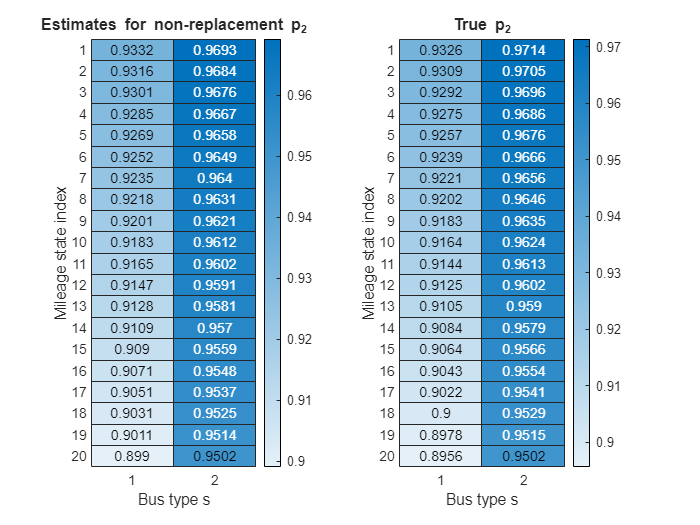

ccp_hat = zeros(length(X),length(S));
epsilon=1e-4;

for j=1:length(X)
    for s=1:length(S)
        ccp_hat(j,s) = max(epsilon, min(1-epsilon,sum(sum(data_d(data_x==X(j) & data_s==S(s))==1))/sum(sum(data_x==X(j) & data_s==S(s)))));
    end
end
ccp_hat(isnan(ccp_hat))=1-epsilon;

%
X_logit=[data_x(:) data_x(:).^2 (data_s(:)==2) (data_s(:)==2).*data_x(:)]';
lambda_hat = mnrfit(X_logit',data_d(:));

ccp_hat_logit=zeros(length(X),length(S));

for s=1:length(S)
    X_logit_fit=[X', X'.^2, (s==2)*ones(size(X,2),1), (s==2).*X' ];
    temp_ccps=mnrval(lambda_hat,X_logit_fit);
    ccp_hat_logit(:,s)=temp_ccps(:,1);
end

ccp_hat = ccp_hat_logit;

% Compare with true CCPs
[~,~,ccps_true] = value_function_iteration(S,F2,X, beta,theta);

figure(1);subplot(1,2,1);h=heatmap(1-ccp_hat(1:20,:));
h.Title='Estimates for non-replacement p_2';h.XLabel = 'Bus type s'; h.YLabel='Mileage state index';
subplot(1,2,2);h2=heatmap(1-ccps_true(1:20,:));
h2.Title='True p_2';h2.XLabel = 'Bus type s'; h2.YLabel='Mileage state index';

### Log-likelihood CCP estimation with terminal state

The specifics of this particular problem allow for conditional choice probability estimation to be especially beneficial. Recall that we can express the difference between the ex-ante valuation $V(x_t)$ and the conditional valuation function $v_j(x_t)$ as a known function of the conditional choice probabilities: $V(x_t) - v_j(x_t) = \psi_j(p(x_t))$. This allows the ex-ante value function to be expressed relative to a reference choice. Certain specifications for the reference choice can greatly simplify the difference in the conditional value functions that comprises the basic component of likelihood-based estimators. 


$$v_1(x) = 0 + \beta \left( \sum_{m=1}^M [v_1(x^m) - \log(p_1(x^m))]f_1(x^m | x) + \gamma\right) = \ 0 + \beta \left( \sum_{m=1}^M [u_1(x^m) - \log(p_1(x^m))]f_1(x^m | x) + \gamma\right) + \beta^2 \sum_{\tilde{m}=1}^M \sum_{m=1}^M V(x^{\tilde{m}})f_1(x^{\tilde{m}} | x^m) f_1(x^m | x)$$



$$v_2(x) = u_2(x) + \beta \left( \sum_{m=1}^M [v_1(x^m) - \log(p_2(x^m))]f_2(x^m | x) + \gamma\right) = \ u_2(x) + \beta \left( \sum_{m=1}^M [u_1(x^m) - \log(p_1(x^m))]f_2(x^m | x) + \gamma\right) + \beta^2 \sum_{\tilde{m}=1}^M \sum_{m=1}^M V(x^{\tilde{m}})f_1(x^{\tilde{m}} | x^m) f_2(x^m | x)$$


With a renewal choice of replacing the engine in the previous period, the last term in each of these conditional value equations is identical: $f_1(x_1 | x) = 1 \ \forall x$. This means that all terms two periods ahead or more will cancel from the differenced conditional values, greatly simplifying the expression of the conditional choice probabilities.


$$v_2(x) - v_1(x) = \mathbf{u}_2(\mathbf{x}) - \beta \log(\mathbf{p}_1(\mathbf{x})) F_2  +  \beta\log(\mathbf{p}_1(\mathbf{x}))F_1 $$


Recalling that $p_2(x) = \ \frac{\exp\Big(v_2(x) - v_1(x)\Big)}{ 1 + \exp\Big(v_2(x) - v_1(x))\Big)}$, we have that  $\frac{\log(p_2(x))}{1 - \log(p_2(x))} = \theta_0 + \theta_1 x + \theta_2 s - \beta \sum_{m=1}^M \big[\gamma - \log(p_1(x^M))\big](f_2(x^m | x) - f_1(x^m | x)$. This forms the basis for the maximum likelihood estimator. 

**Identifying and estimating **$\beta$: The formulation using the moment conditions helps to consider identification along other dimensions than estimating the "normal" parameters. In the above equation, it is clear that as long as the conditional choice probabilities and state transitions satisfy a rank condition, we can identify and estimate $\beta$, as it is simply another parameter that enters linearly. In general, $\beta$ is not identified. We saw on the previous set of notes that we had exactly one moment condition per state, so $\mathbf{u}_2(x)$ we just identified given the other assumptions (known $\beta$ and distribution for $\epsilon$). However, the additional structure on this problem, i.e. our parametric functional form restriction on utility plus the terminal state/renewal choice. In this setting, we have sufficient restrictions to point-identify the discount factor.

Can we always identify $\beta$ when we have linear utility? In general the answer is no. Abbring, J. H., & Daljord, Ø. (2020) provide results that characterize the identification of the time discount factor, which in general remains non-point identified even with strong functional form assumptions on utility.


temp_ccp_lik = @(theta) ccp_likelihood(theta,X,S,f,data_x_index,data_s,data_d,ccp_hat,beta);
theta_0=0.1*ones(4,1);
options = optimoptions('fminunc','Display','none');
[theta_hat_ccp,f_val] = fminunc(temp_ccp_lik,theta_0,options);
CCP_EstimatesTable = table(theta_hat_ccp,[theta'; beta],'VariableNames',{'Finite-dependence CCP','True values'},'RowNames',{'Theta0','Theta1','Theta2','Beta'})

CCP_EstimatesTable = 4×2 table
              Finite-dependence CCP    True values
              _____________________    ___________

    Theta0            2.0791                  2   
    Theta1          -0.15009              -0.15   
    Theta2           0.92378                  1   
    Beta             0.89248                0.9   


### 1.5 Linear CCP estimation with terminal state

Note that we don't necessarily need to use the logit maximum likelihood to estimate the structural parameters. We can specify this in closed form using the moment conditions discussed above. Let's revisit the moment conditions that establish identification:


$$\frac{\log(p_2(x))}{1 - \log(p_2(x))} = \theta_0 + \theta_1 x + \theta_2 s - \beta \sum_{m=1}^M \big[\gamma - \log(p_1(x^M))\big](f_2(x^m | x) - f_1(x^m | x)$$


This fits directly into a linear regression estimator that we can express in closed form. This method forms the basis for Kalouptsidi et al. (2021), among other estimators.


all_states = [X', ones(length(X),1); X', 2*ones(length(X),1)];
beta_factor = [(F2-F1)*(emc-log(ccps_true(:,1))); (F2-F1)*(emc-log(ccps_true(:,2)))];
X_reg = [ones(size(all_states,1),1) all_states, beta_factor];
Y_reg = log(1-ccps_true(:)) - log(ccps_true(:));

format shortG
ThetaHat_Beta = (X_reg'*X_reg)\(X_reg'*Y_reg);
CCP_LinearEstimaionsTable = table(ThetaHat_Beta,[theta'; beta],'VariableNames',{'Finite-dependence CCP','True values'},'RowNames',{'Theta0','Theta1','Theta2','Beta'})

CCP_LinearEstimaionsTable = 4×2 table
              Finite-dependence CCP    True values
              _____________________    ___________

    Theta0                2                   2   
    Theta1            -0.15               -0.15   
    Theta2                1                   1   
    Beta                0.9                 0.9   


**Full-information maximum likelihood Estimation** 

fiml_fun = @(theta) FIML_log_likelihood(theta,data_x,data_s,data_d,X,S,data_x_index,f,beta);

theta_0=0.1*ones(3,1);
options = optimoptions('fminunc','Display','none');
[theta_hat,~] = fminunc(fiml_fun,theta_0,options);
FIML_EstimatesTable = table(theta_hat,theta','VariableNames',{'FIML estimates','True values'})

FIML_EstimatesTable = 3×2 table
    FIML estimates    True values
    ______________    ___________

         2.0159              2   
       -0.14946          -0.15   
          1.006              1   


## 2. Labor model with two-period finite dependence.

This section describes and estimates a labor model that is much-simplified version of Keane and Wolpin (1997). Workers make a choice about whether they would like to work in a blue collar occupation, and white collar occupation, or stay at home (unemployment or home production). Current labor market choices have an impact on future outcomes through human capital accumulation. In this very simple model, we will assume that human capital takes the form of experience only, and that experience separately accrues in blue collar and white collar occupations (although blue collar experience may be beneficial for white collar work and vice versa). 

We abstract from many features common to dynamic models of labor force participation, such as wage processes, fertility, and so on, and instead assume that flow utilities are linear functions of experience and, when working, a cost of switching occupations. These switching costs are also applicable to applications in quantitative marketing when modeling, for example, consumers' behavior to switch between products.

### 2.1 Setup and model

- Time is discrete, with an annual discount factor $\beta$. Each period corresponds to one year.

- The model tracks workers through their working lives until retirement. We assume that we observe workers starting at age 35 ($t=1$) and that workers permanently exit the labor market at age 65 so that the last age a labor choice is made is age 64 ($T=30$).

- In period $t$, individual $i$ decides whether to work in a blue collar job $d_{iBt}=1$, a white collar job $d_{iWt}=1$, or stay at home and not work $d_{iHt}=1$. As usual, the options are mutually exclusive so that $d_{iBt} + d_{iWt} +d_{iHt}=1$ and $d_{ijt} \in \{0,1\}$ for each $j \in \{B,W,H\}$.

- Workers accumulate human capital through work experience. Denote by $C_{iBt}$ the total experience (human capital) of individual $i$ in blue collar jobs and $C_{iWt}$ the total experience of individual $i$ in white collar jobs. 

- Utility for working in blue collar and white collar jobs is given by


$$u_{iBt}(x_t) = \theta_1^B + \theta^B_2 C_{iBt} + \theta^B_3 C_{iWt} + \theta^B_4 \cdot 1\{d_{iBt-1}\neq 1\}$$$



$$u_{iWt}(x_t) = \theta^W_1 + \theta^W_2 C_{iBt} + \theta^W_3 C_{iHt} + \theta^W_4 \cdot 1\{d_{iWt-1}\neq 1\} $$


- The state variable $x_{it} \equiv [C_{iBt}, \ C_{iWt}, \ 1-d_{iBt-1}, \ 1-d_{iWt-1}]$ includes the human capital accumulated in each work type and indicator variables for whether individual $i$ is subject to a switching cost in period $t$.

- $\theta^j_1$ is the (dis)utility from work of type $j \in \{B,W\}$, $\theta^j_3$ captures the "switching cost" associated with moving to a different work type. We set the deterministic component of utility from one option to a known value; in this case, $u_{iHt}= 0$ for all $i, t$. 

- Total utility in period $t$ includes an i.i.d. shock term $\epsilon_{ijt} \sim$ Type I Extreme Value, so that flow utility is given by $u_{ijt}(x_{it}) + \epsilon_{ijt}$ for each period $t$, individual $i$, and labor choice $j$.

#### State transitions

- State transitions are deterministic.

- If staying at home is chosen, $d_{iHt}=1$, then human capital for both blue collar and white collar work remain unchanged ( $H_{ijt+1} = H_{ijt}, \ j \in \{B,W\}$). Both switching cost indicators in the next period are equal to one.

- If blue collar work is chosen, $d_{iBt}=1$, then blue collar human capital increases by one unit, $H_{iBt+1}=H_{iBt}+1$, while white collar human capital is unchanged. The blue collar switching cost indicator in period $t+1$ is "off" while the white collar switching cost in period $t+1$ is "on." A similar transition happens if white collar work is chosen.

- Denote by $f_j(x_{it+1} | x_{it})$ to be the state transition matrix for labor choice $j$. Because transitions are deterministic, each row consists of a single "one" corresponding to the index for next periods state, with the remaining row entries equal to zero.

**Non-stationarity.** 

This model is *non-stationary. *In the bus engine model, conditional on a state $x$, it did not matter in which time period a decision was made. The future always looks the same, because time continues forever and the state transitions never chage. This implies that the conditional choice probabilities do not depend on the time period, generating the simple represenations for value functions that we saw above.

With a finite time horizon this is no longer the case. As the last period approaches, evolutions of state variables that benefit the future utility for the decision maker become less valuable. In the context of human capital accumulation, we would not expect people to care about obtaining more skills and education when they are close to retirement age. 

Mathematically, we have a non-stationary environment if either of the following hold

- There exists a choice $j$, two periods $t, \tau$, and state $x$ such that $u_{j\tau}(x) \not= u_{jt}(x)$,

- There exists a choice $j$, two periods $t, \tau$, and states $x$ and $x'$ such that  $f_{j\tau}(x' | x) \not= f_{jt}(x' | x)$, or

- The time horizon is finite: $T<\infty$.

In this model, we have the third condition. That means we don't have to index utility or state transitions by time, but we *do* have to index value functions and conditional choice probabilities by time. One thing to remember: when the model is non-stationary, *time is a state variable*.

#### Conditional value functions and choice probabilities

- The conditional value functions are 


$$v_{Ht}(x_{t}) = \ 0 + \beta \sum_{x=1}^{\overline{x}} V(x) f_H(x \ | x_{t+1})$$



$$v_{Bt}(x_t) = u_{iBt} + \beta \sum_{x=1}^{\overline{x}} V(x) f_B(x \ | x_{t+1})$$



$$v_{Wt}(x_t) = u_{iWt} + \beta \sum_{x=1}^{\overline{x}} V(x) f_W(x \ | x_{t+1})$$


- In particular, note that we must index the conditional value functions by time, as the finite time horizon makes this problem non-stationary.

- The conditional choice probabilities are expressed as


$$p_t(j | x_{it}) \ = \ \frac{\exp\Big(v_{jt}(x_{it}) \Big)}{ \sum_{k \in \{H,B,W\}}\exp\Big(v_{kt}(x_{it}) \Big)} $$


### 2.2 Finite dependence representation

- These problems can, in many instances, be substantially more computationally burdensome than stationary, infinite-horizon models such as the Rust (1987) setup. The reason is that finding the value function for a given set of parameters involves backward induction from the final period $T$, working backward period-by-period to compute the ex-ante value function $V_t(x)$ for all periods $t=T,T-1,...,1$and states $x \in \mathcal{X}$. When the state space is very large or there are many periods, this can take a very long time.

- Finite dependence helps because it does not require looking all the way into each individual's future until the retirement age $T$. If there is $\rho$ period finite dependence, we simply need to look $\rho$ periods in the future.

- In the renewal model of Rust (1987), we need one-period ahead choice probabilities due to engine replacement. In this setting, we need two-period ahead choice probabilities.

- Consider an individual in period $t$ with state vector $x_{t} = [h_{Bt}, \ 0, \ h_{Wt}, \ 0]$ who can follow two potential work histories. The first is to work blue collar job in period $t$, then stay at home in period $t+1$, and works in a blue collar job in period $t+2$.  The second is to stay at home in period $t$ and work in a blue collar job in periods $t+1$ and $t+2$. 


$$[h_{Bt}, \ h_{iWt}, \ 1, \ 1] \quad \underset{d_{Bt}=1}{\longrightarrow} \quad [h_{Bt}+1, \ h_{Wt}, \ 0, \ 1]  \quad \underset{d_{Ht+1}=1}{\longrightarrow} \quad [h_{Bt}+1, \ h_{Wt}, \ 1, \ 1] \quad \underset{d_{Bt+2}=1}{\longrightarrow} \quad [h_{Bt}+2, \ h_{Wt},  \ 1, \ 0]$$



$$[h_{Bt}, \ h_{Wt}, \ 1, \ 1] \quad \underset{d_{Ht}=1}{\longrightarrow} \quad [h_{Bt}, \ h_{Wt}, \ 1, \ 1]  \quad \underset{d_{Bt+1}=1}{\longrightarrow} \quad [h_{Bt}+1, \ h_{Wt}, \ 0, \ 1] \quad \underset{d_{Bt+2}=1}{\longrightarrow} \quad [h_{Bt}+2, \ h_{Wt}, \ 1, \ 0]$$


- A similar pattern holds for an initial choice pair of $(H, \ W)$.

- This sequence can be constructed for all states and time periods, meaning that for all states $x$ and time periods $t$, we can find two distinct sequence of choices such that the same state is reached after two periods of following either choice sequence. This gives us two-period finite dependence.

- Recall that we can express the utility for a choice $j$ by expanding out a sequence of choices of the reference utility $u_H(x_{it})$:


$$u_{jt}(x_t) = u_H(x_t) + \psi_{Ht}(x_t) - \psi_{jt}(x_t)  \\ + \sum_{\tau = t+1}^S \sum_{x \in X} \beta^{\tau - t} [u_{H}(x_{\tau}) + \psi_{H \tau}(x_{\tau})]\times[\kappa_{\tau-1}(x_{\tau} | x_t, H) - \kappa_{\tau-1}(x_{\tau} | x_t, j)] \\
+ \sum_{x \in X} \beta^{S-t} V_{S+1}(x_{S+1}) [\kappa_{S}(x_{S+1} | x_t, H) - \kappa_{S}(x_{S+1} | x_t, j)]$$


where $\kappa_{\tau} (\cdot | \cdot)$ is defined with respect to a sequence of decisions $\{d^*_{j\tau}\}$ for $\tau = t+1,...,S$ as


$$\kappa_{\tau}(x_{\tau +1} | x_t, j) = \begin{cases} f_{j}(x_{t+1} | x_t) & \mbox{if } \ \tau=t+1 \\ \sum_{x_{\tau} \in X} \sum_{k\in \{H,B,W\}} d^*_{j\tau} \ f_k(x_{\tau+1} | x_{\tau})\kappa_{\tau-1}(x_{\tau} | x_t, j)  & \mbox{otherwise.} \end{cases}$$


- What this means in our case is that we can use the utility expression above for two choices $(j,H)$, define two sequences of decisions $\{d^*_{j\tau}\}, \{\tilde{d}_{j\tau}\}$ that satisfy the two-period finite dependence discussed above, and cancel all terms beyond $t+2$ as the ex-ante value functions will be exactly the same across these two sequences.

- Specifically, we have that 


$$u_{jt}(x_t) + \psi_{j}(p_t(x_t)) - u_H(x_t) -\psi_{H}(p_t(x_t)) \\ = \\ \sum_{k \in \{H,B,W\}} \sum_{\tau=t+1}^{t+2} \sum_{x \in X} \beta^{\tau - t} [u_{k\tau}(x_\tau) + \psi_k(p_{\tau}(x_{\tau})] \times[d^*_{k\tau} \kappa_{\tau}(x_{\tau} | t ,x_t, H) - \tilde{d}_{k\tau} \kappa_{\tau}(x_{\tau} | t ,x_t, j)]$$


- Everything in this equation can is linear in the parameter vector $\theta$ or is a function of the conditional choice probabilities $p_t(x_t)$ or state transitions $f_j(\cdot | \cdot)$. 

- This equation forms a moment that is used for establishing identification and in constructing an estimator (in closed form, as long as utilities are linear in the unknown parameters).

- We have one such equaction for each choice pair $(H,j)$, state $x_t$, and time period $t$ for which two-period finite dependence holds.

- All that remains is to calculate the conditional choice probabilities and re-arrange the above equation so that it can be easily expressed as a linear function of the parameters.

### 2.3 Estimation with conditional choice probabilities

Now we take the model to (simulated) data. We make a few assumptions when generating the data to keep things simple and running quickly:

- The maximum human capital of either type is 6 (i.e., additional experience beyond 6 years does not increase per-period utility).

- The number of individuals $N=5,000$.

- The number of time periods is $T=30$ for each person in the sample.

- Structural parameters used to generate the data are


$$\beta = 0.95, \quad \theta^B = \left( \begin{array}{c} -1 \\ 0.15 \\ 0.15 \\ -1.5 \end{array} \right), \quad  \theta^W = \left( \begin{array}{c} -1 \\ 0.2 \\ 0.15 \\ -1.6 \end{array} \right)$$


clear;
d_len=3; % Number of choices
HB_max=6; % Maximum blue collar human capital
HW_max=6; % Maximum white collar human capital

H_list=repmat((0:HB_max)',[HW_max+1,1]);
X_temp=[H_list, sort(H_list,'ascend')];
% This defines the set of all states. Note that we cannot have
% both switching costs equal to zero, as that would imply working in both
% sectors in a single period.
X=[repmat(X_temp,[3,1]), [ones(size(X_temp,1),1), ones(size(X_temp,1),1); ones(size(X_temp,1),1), zeros(size(X_temp,1),1); 
    zeros(size(X_temp,1),1) ones(size(X_temp,1),1)]];
x_len=size(X,1);
xtran_1=zeros(x_len);
xtran_2=zeros(x_len);
xtran_3=zeros(x_len);
for j=1:x_len
    [~,new_state]=ismember([X(j,1),X(j,2),1,1],X,'rows');
    xtran_1(j,new_state)=1;
    if X(j,1)<HB_max
        [~,new_state]=ismember([X(j,1)+1,X(j,2),0,1],X,'rows');
        xtran_2(j,new_state)=1;
    else
        [~,new_state]=ismember([HB_max,X(j,2),0,1],X,'rows');
        xtran_2(j,new_state)=1;
    end
    if X(j,2)<HW_max
        [~,new_state]=ismember([X(j,1),X(j,2)+1,1,0],X,'rows');
        xtran_3(j,new_state)=1;
    else
        [~,new_state]=ismember([X(j,1),HW_max,1,0],X,'rows');
        xtran_3(j,new_state)=1;
    end
end
x_tran=zeros(x_len,x_len,d_len);
x_tran(:,:,1)=xtran_1;x_tran(:,:,2)=xtran_2;x_tran(:,:,3)=xtran_3;
% x_tran(:,:,j) is the state transition matrix for choice j

#### **Verifying finite dependence**

Just in case you don't trust me about two period finite dependence in this model, let's quickly verify that it holds. We can do this simply by comparing the transition probabilities for the pairs of choices outlined in the example above. We simply need to multiply the transition matrices together in the order corresponding to the two (proposed) finite dependence paths and check if check if the two paths generate the same transition matrix over states in period $t+3$. If that is the case, then the $t+3$ ex-ante value function expressions will cancel when the taking the difference between the conditional value functions.

**Path one**: Sequence A is $(H,B,B)$ and sequence B is $(B,H,B)$.

path_one_A = x_tran(:,:,1)*x_tran(:,:,2)*x_tran(:,:,2);
path_one_B = x_tran(:,:,2)*x_tran(:,:,1)*x_tran(:,:,2);
path_one_check=isequal(path_one_A,path_one_B)

path_one_check = logical
   1


**Path two: **First sequence is $(H,W,W)$, and the second sequence is $(W,H,W)$.

path_two_A = x_tran(:,:,1)*x_tran(:,:,3)*x_tran(:,:,3);
path_two_B = x_tran(:,:,3)*x_tran(:,:,1)*x_tran(:,:,3);
path_two_check=isequal(path_two_A,path_two_B)

path_two_check = logical
   1



% True parameter values:
theta=[-1;0.15;0.15;-1.5;-1;0.2;0.15;-1.6];
beta=0.95;
T=30;
N=5000;
[data_t, data_n, data_x, data_d, data_x_index] = generate_labor_data(N, T, x_tran, X, beta,theta);
T_data=data_t(:);X_data=data_x(:);D_data=data_d(:);X_index_data=data_x_index(:);N_data=data_n(:);
X_data=X(X_index_data,:);



#### Conditional choice probability estimation

**Calculating the true CCPs.** The (optional) first step is to calculate the true CCPs using the true parameter vector $\theta^0$. While not strictly necessary for estimation, in practice it is useful to perform this step when writing the estimation code to verify that things are working correctly and, sometimes, for benchmarking purposes. If the CCP estimator for $\theta$ does not return values close to $\theta^0$ when the true CCPs are used, then something is going wrong!

% True CCPs:
emc = double(eulergamma);
value_function = zeros(x_len,T);
u1 = 0;
u2 = theta(1) + theta(2)*X(:,1) + theta(3)*X(:,2) + theta(4)*X(:,3);
u3 = theta(5) + theta(6)*X(:,1) + theta(7)*X(:,2) + theta(8)*X(:,4);

ccp_true=zeros(size(X,1),d_len,T);
value_function(:,T)=log(exp(0)+exp(u2)+exp(u3))+emc;
ccp_true(:,1,T)=exp(0)./(exp(0)+exp(u2)+exp(u3));
ccp_true(:,2,T)=exp(u2)./(exp(0)+exp(u2)+exp(u3));
ccp_true(:,3,T)=exp(u3)./(exp(0)+exp(u2)+exp(u3));
for t=T-1:-1:1    
    v1 = beta*(x_tran(:,:,1)*value_function(:,t+1));
    v2 = u2 + beta*(x_tran(:,:,2)*value_function(:,t+1));
    v3 = u3 + beta*(x_tran(:,:,3)*value_function(:,t+1));
    ccp_true(:,1,t)=exp(v1)./(exp(v1)+exp(v2)+exp(v3));
    ccp_true(:,2,t)=exp(v2)./(exp(v1)+exp(v2)+exp(v3));
    ccp_true(:,3,t)=exp(v3)./(exp(v1)+exp(v2)+exp(v3));
    value_function(:,t)=log(exp(v1)+exp(v2)+exp(v3)) + emc;
end



**Estimating the CCPs:**

To estimate conditional choice probabilities in each time period and state, we could use the non-parametric maximum likelihood estimator given by

$\hat{p}_{tj}(x) = \frac{\sum_{n=1}^N  \mathbf{1}\{x_{nt}=x, \ d_{jnt} = 1\}}{\sum_{n=1}^N  \mathbf{1}\{x_{nt}=x\}}$.

However, in practice it is common to use a parametric estimator for the conditional choice probabilities, as the non-parametric estimator can be imprecise when the number of observations per state-period pair are small.

Instead, we fit the conditional choice probabilities to a multinomial logit model. We can specify this in a flexible way to increase prediction accuracy, for instance by including polynomial and interaction terms. In the specification below I include squared terms for human capital and time and a time-human capital interaction term. Matlab has a built-in command for multinomial regression, mnrfit, which works well for this purpose.

start_ccp=tic;
%Logit regression for ccp hat
X_logit=[data_x data_x(:,1:2).^2 data_t(:) (1./10)*data_t(:).^2 data_t(:).*data_x(:,1:2)]';
lambda_hat = mnrfit(X_logit',D_data);

ccp_hat_logit=zeros(size(X,1),d_len,T);

for t=1:T
    X_logit_fit=[X X(:,1:2).^2 t*ones(x_len,1) (1./10)*t^2*ones(x_len,1) t*X(:,1:2) ];
    ccp_hat_logit(:,:,t)=mnrval(lambda_hat,X_logit_fit);
end
ccp_hat = ccp_hat_logit;
%ccp_hat=ccp_true;


#### **Closed-form estimator for **$\theta$. 

With estimates for the conditional choice probabilities, we can express the estimator for $\theta$. To illustrate this, we will use the example of the first pair of sequences where Sequence A is $(H,B,B)$ and sequence B is $(B,H,B)$. Because the estimator can be expressed and calculated in closed form using matrix notation, we will switch to that notation here. Define the following:


$$U_j = \left[ \begin{array}{c} u_j(x_1) \\ \vdots \\ u_j(x_X) \end{array} \right], \qquad F_j = \left[ \begin{array}{c c c} f_j(x_1 | x_1) & \cdots & f_j(x_X | x_1) \\ \vdots & \ddots & \vdots \\ f_j(x_X | x_1)  & \cdots & f_j(x_X | x_X) \end{array} \right], \qquad \Psi_{jt} = \left[ \begin{array}{c} \psi_j(p_t(x_1)) \\ \vdots \\ \psi_j(p_t(x_X)) \end{array} \right]$$


Fix a starting time period $t$. Re-expressing the two-period finite dependence equation from section 1.4 using Sequence A and Sequence B gives


$$U_B + \Psi_{Bt} - U_H - \Psi_{Ht} = \beta\left[ F_H(U_B + \Psi_{Bt}) - F_B(U_H + \Psi_{Ht})\right] 
 \\ \qquad \qquad \qquad \qquad \qquad+ \beta^2 \left[ F_HF_B(U_B + \Psi_{Bt}) - F_BF_H(U_B + \Psi_{Bt})\right] 

$$


Moving all terms involving utilities to the left-hand side and all other terms to the right-hand side and recalling that $U_H=0$ gives


$$U_B - \beta F_HU_B - \beta^2 \left[ F_HF_BU_B - F_BF_HU_B \right] = \Psi_{Ht} -\Psi_{Bt} + \beta\left[ F_H \Psi_{Bt} - F_B\Psi_{Ht}\right] + \beta^2 \left[ F_HF_B\Psi_{Bt} - F_BF_H \Psi_{Bt}\right]$$


The last step is to express $U_B = X*\theta^B$:


$$\Big(X - \beta F_HX - \beta^2 \left[ F_HF_BX - F_BF_HX \right]\Big)\theta^B = \Psi_{Ht} -\Psi_{Bt} + \beta\left[ F_H \Psi_{Bt} - F_B\Psi_{Ht}\right] + \beta^2 \left[ F_HF_B\Psi_{Bt} - F_BF_H \Psi_{Bt}\right]$$


This last step makes clear that the linear functional form for $u_j$ allows the estimator for $\theta$ to be expressed in closed form. Define 


$$Y_t^B =  \Psi_{Ht} -\Psi_{Bt} + \beta\left[ F_H \Psi_{Bt} - F_B\Psi_{Ht}\right] + \beta^2 \left[ F_HF_B\Psi_{Bt} - F_BF_H \Psi_{Bt}\right]$$



$$Z_t^B = X - \beta F_HX - \beta^2 \left[ F_HF_BX - F_BF_HX \right]$$


An estimator for $\theta^B$ using only data from period $t$ would be $\hat{\theta}^B(t) = \arg \min_{\theta} (Y_t^B - Z_t^B\theta)'*W*(Y_t^B - Z_t^B\theta)$. We can simply use the "normal" linear regression estimator $\hat{\theta}^B(t) =[(Z_t^B)'*Z_t^B]^{-1}\times(Z_t^B)'*Y^B_t)$.

To generalize to other time periods and include estimation of $\theta^W$, define $Y^W_t$ and $Z^W_t$ analogously as above. 


$$\mathbf{Y}=\left( \begin{array} {c c} Y^B & \mathbf{0} \\ \mathbf{0} & Y^W \end{array} \right), \qquad \mathbf{Z} = \left( \begin{array} {c c} Z^B & \mathbf{0} \\ \mathbf{0} & Z^W \end{array} \right)$$


The minimum distance estimator is given by


$$\hat{\theta} = \arg \min_{\theta} \left(\mathbf{Y} - \mathbf{Z} \theta)'*W*\left(\mathbf{Y} - \mathbf{Z} \theta)$$


for a positive definite weighting matrix $W$. Again, for simplicity we can just use the linear regression estimator here: $\hat{\theta} = (\mathbf{Z}'\mathbf{Z})^{-1}\mathbf{Z}'\mathbf{Y})$.



X_u2=[ones(size(X,1),1) X(:,1:3)];
X_u3=[ones(size(X,1),1) X(:,[1,2,4])];
Z_2 = zeros(x_len,T-2); Z_3 = Z_2;
Y_2 = X_u2 - beta*x_tran(:,:,1)*X_u2 - (beta^2)*x_tran(:,:,1)*x_tran(:,:,2)*X_u2 + (beta^2)*x_tran(:,:,2)*x_tran(:,:,1)*X_u2;
Y_3 = X_u3 - beta*x_tran(:,:,1)*X_u3 - (beta^2)*x_tran(:,:,1)*x_tran(:,:,3)*X_u3 + (beta^2)*x_tran(:,:,3)*x_tran(:,:,1)*X_u3;
for t=1:T-2
    Z_2(:,t) = -log(ccp_hat(:,1,t)) + log(ccp_hat(:,2,t)) + beta*(x_tran(:,:,1)*(-log(ccp_hat(:,2,t+1))) - x_tran(:,:,2)*(-log(ccp_hat(:,1,t+1)))) ...
        + (beta^2)*(x_tran(:,:,1)*x_tran(:,:,2)*(-log(ccp_hat(:,2,t+2))) - (x_tran(:,:,2)*x_tran(:,:,1)*(-log(ccp_hat(:,2,t+2)))));
    Z_3(:,t) = -log(ccp_hat(:,1,t)) + log(ccp_hat(:,3,t)) + beta*(x_tran(:,:,1)*(-log(ccp_hat(:,3,t+1))) - x_tran(:,:,3)*(-log(ccp_hat(:,1,t+1)))) ...
        + (beta^2)*(x_tran(:,:,1)*x_tran(:,:,3)*(-log(ccp_hat(:,3,t+2))) - (x_tran(:,:,3)*x_tran(:,:,1)*(-log(ccp_hat(:,3,t+2)))));
end


X_block1=repmat(Y_2,[T-2,1]); % This is Z^B
X_block2=repmat(Y_3,[T-2,1]); % This is Z^W
X_reg=[X_block1, zeros(size(X_block1));
    zeros(size(X_block2)), X_block2];
Y=[Z_2(:);Z_3(:)]; 

%obj_fun = @(theta) (Y-X_reg*theta)'*(Y-X_reg*theta);
%[theta_hat_ccp, fval] = fminunc(obj_fun,ones(8,1));

states_num=zeros(size(X,1)*(T-2),1);
for j=1:size(X,1)
    for t=1:T-2
        states_num((t-1)*j+j)=sum(data_x_index(:)==j & data_t(:)==t);
    end
end
W = diag(states_num./(size(data_d(:),1)));
W2=1e3*[W, zeros(size(W)); zeros(size(W)), W];
ThetaHatCCP_Weighted = (X_reg'*W2*X_reg)\(X_reg'*W2*Y);
table(ThetaHatCCP_Weighted,theta,'VariableNames',{'Weighted min. dist. estimates','True values'})

ans = 8×2 table
    Weighted min. dist. estimates    True values
    _____________________________    ___________

               -1.5315                    -1    
               0.23736                  0.15    
               0.16752                  0.15    
               -1.5167                  -1.5    
               -1.1528                    -1    
               0.20855                   0.2    
               0.16183                  0.15    
               -1.6093                  -1.6    


toc(start_ccp)

Elapsed time is 16.564410 seconds.


**Full information maximum likelihood**

We include a full information maximum likelihood for reference, again with the caveat that this is an extremely slow (but simple to code) version of the nested fixed point estimation method.

FIML_fun=@(theta) FIML_log_likelihood_labor(theta,T,data_d, data_t,X,data_x_index,x_tran,beta);
options = optimoptions("fminunc","MaxFunctionEvaluations",10000);
[theta_hat_fiml,fval]=fminunc(FIML_fun,ones(8,1),options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


## Functions

### CCP likelihood with finite dependence

function [ccp_lik] = ccp_likelihood(theta,X,S,x_tran,data_x_index,data_s,data_d,ccp_hat,beta)
emc = double(eulergamma);

GIven a set of estimated conditional choice probabilities, we can compute the likelihood associate with a set of parameters $\theta, \beta$ in four steps.

- First, we define the values for flow utility of not replacing for all states. This gives an $|X| \times |S|$ matrix of flow utilities.

- Next, we calculate each component term from the differenced value equation, recognizing that we can ignore all terms two or more periods ahead due to finite dependence. First is the conditional value for replacing the engine $j=1$, which is given by $v_1^{(CCP)} = \beta \left( \sum_{m=1}^M [u_1(x^m) - \log(p_1(x^m))]f_1(x^m | x) + \gamma\right)$. This term is the same for all intial states $x$, as the state transition function $f_1(\cdot | \cdot)$ sends all states to zero mileage and $u_1(x^m)=0$ by assumption. 

- We do the same for the conditional value function for not replacing $j=2$. This is $v_2^{(CCP)} = u_2(x) + \beta \left( \sum_{m=1}^M [u_1(x^m) - \log(p_1(x^m))]f_1(x^m | x) + \gamma\right)$ for each state $x$. We can stack the utilities and calcuate this with a single equation.

- Finally, we calculate the likelihood as $\mathcal{L}(\theta ; \{x_{nt},d_{nt}\}) = \sum_{n=1}^N \sum_{t=1}^T d_{2nt} \Big(v_2^{(CCP)}(x_{nt})  - v_1^{(CCP)}(x_{nt})\Big) - \log\Big(1 + \exp(v_2^{(CCP)}(x_{nt})  - v_1^{(CCP)}(x_{nt}) \Big)$.


% Step 1:
u2 = theta(1) + theta(2)*X' + theta(3)*S;
% Step 2:
v1_ccp = repmat(theta(end)*(-log(ccp_hat(1,:))) + theta(end)*emc,[length(X),1]); 
% Step 3:
v2_ccp = u2 + theta(end)*x_tran(:,:)*(0 - log(ccp_hat(:,:))) + theta(end)*emc;
% Step 4:
x_s_index = sub2ind(size(v2_ccp), data_x_index(:), data_s(:));
ccp_lik = -sum((data_d(:)==2).*(v2_ccp(x_s_index)-v1_ccp(x_s_index)) - log(1+exp(v2_ccp(x_s_index)-v1_ccp(x_s_index)))); % Add the negative as the optimizer performs minimization, not maximization.


end


### Full-information maximum likelihood

function [fiml_lik] = FIML_log_likelihood(theta,data_x,data_s,data_d,X,S,data_x_index,x_tran,beta)

value_function = value_function_iteration(S,x_tran,X,beta,theta);

D_temp = data_d(:);
S_temp = data_s(:);
X_index_temp = data_x_index(:);

v1 = repmat(beta*value_function(1,S),[length(X),1]);
v2 = theta(1) + theta(2)*X' + theta(3)*S + beta*(x_tran(:,:)*value_function(:,:));

x_s_index    = sub2ind(size(v2), X_index_temp, S_temp);
fiml_lik = -sum((D_temp==2).*(v2(x_s_index)-v1(x_s_index)) - log(1+exp(v2(x_s_index)-v1(x_s_index))));

end


function [fiml_lik] = FIML_log_likelihood_labor(theta,T,data_d,data_t,X,data_x_index,x_tran,beta)

value_function = backwards_induction(x_tran,X,T,beta,theta);
value_function=[value_function,zeros(size(X,1),1)];
D_temp = data_d(:);
T_temp=data_t(:);
X_index_temp = data_x_index(:);

u1 = 0;
u2 = theta(1) + theta(2)*X(:,1) + theta(3)*X(:,2) + theta(4)*X(:,3);
u3 = theta(5) + theta(6)*X(:,1) + theta(7)*X(:,2) + theta(8)*X(:,4);
v1=zeros(size(X,1),T);v2=v1;v3=v1;
for t=1:T
    v1(:,t) = u1 + beta*x_tran(:,:,1)*value_function(:,t+1);
    v2(:,t) = u2 + beta*x_tran(:,:,2)*value_function(:,t+1);
    v3(:,t) = u3 + beta*x_tran(:,:,3)*value_function(:,t+1);
end

x_t_index    = sub2ind(size(v2), X_index_temp, T_temp);
exp_diff=(D_temp==1).*v1(x_t_index)+(D_temp==2).*v2(x_t_index)+(D_temp==3).*v3(x_t_index);
fiml_lik = -sum(-log(exp(v1(x_t_index)-exp_diff)+exp(v2(x_t_index)-exp_diff)+exp(v3(x_t_index)-exp_diff)));

end


### Data generation

Bus engine replacement

function [data_t, data_x, data_s, data_d, data_x_index] = generate_data(N, T, S, x_tran, x_tran_cumul, X, beta,pi,theta)
    
    initial_run=5; % We start the state variables at zero and let the model run for five periods before we start sampling
    x_index = ones(N, T+initial_run); 
    x_sim = zeros(N,T+initial_run);
    
    s_sim  = (rand(N,1) > pi) + 1;
    d_sim  = zeros(N, T+initial_run); 
    draw_ccp = rand(N, T+initial_run);
    draw_x  = rand(N, T+initial_run);

    value_function = value_function_iteration(S,x_tran,X,beta, theta);
    for n = 1:N
        for t = 1:T+initial_run
            % j=1 replace 
            u1 = 0.0;
            v1 = u1 + beta*value_function(1,s_sim(n)); % Reset to zero mileage deterministically if engine is replaced.
            % j=2 is continue
            u2 = theta(1) + theta(2) * X(x_index(n,t)) + theta(3) * s_sim(n);
            v2 = u2 + beta* x_tran(x_index(n,t),:)*value_function(:,s_sim(n));
            
            % Conditional choice probability
            p1 = exp(v1)/(exp(v1)+exp(v2)); 

            % Simulate next period
            d_sim(n,t)    = (draw_ccp(n,t) > p1) + 1; % 1: replace, 2: continue
            x_index(n,t+1) = (d_sim(n,t)==2) * sum((draw_x(n,t) > x_tran_cumul(x_index(n,t),:))) + 1; 
            x_sim(n,t+1) = X(x_index(n,t+1));
        end
    end
    
    data_x = x_sim(:, initial_run+1:T+initial_run);
    data_d = d_sim(:, initial_run+1:T+initial_run);
    data_s = repmat(s_sim,  [1,T]);
    data_t = repmat(transpose(1:T), [1,N])';
    [~, data_x_index] = ismember(data_x,X); 
    
    return 

end



Labor choice with human capital accumulation

function [data_t, data_n, data_x, data_d, data_x_index] = generate_labor_data(N, T, x_tran, X, beta,theta)
rng(122022);
    initial_run=0; 
    x_index = ones(N, T+initial_run); 
    
    % randomize starting states:
    x_index(:,1)=randi(size(X,1),[N,1]);
    d_sim  = zeros(N, T+initial_run); 
    draw_ccp = rand(N, T+initial_run);
    

    value_function = backwards_induction(x_tran,X,T,beta, theta);
    value_function=[value_function,zeros(size(X,1),1)];
    for n = 1:N
        for t = 1:T+initial_run
            % j=1 stay at home
            u1 = 0.0;
            v1 = u1 + beta*x_tran(x_index(n,t),:,1)*value_function(:,t+1); 
            % j=2 is Blue collar job
            u2 = theta(1) + theta(2)*X(x_index(n,t),1) + theta(3)*X(x_index(n,t),2) + theta(4)*X(x_index(n,t),3);
            v2 = u2 + beta* x_tran(x_index(n,t),:,2)*value_function(:,t+1);

            % j=3 is White collar job
            u3 = theta(5) + theta(6)*X(x_index(n,t),1) + theta(7)*X(x_index(n,t),2) + theta(8)*X(x_index(n,t),4);
            v3 = u3 + beta* x_tran(x_index(n,t),:,3)*value_function(:,t+1);

            % Conditional choice probability
            p2 = exp(v2)/(exp(v1)+exp(v2)+exp(v3)); 
            p3 = exp(v3)/(exp(v1)+exp(v2)+exp(v3));
            p1= 1-(p2+p3);

            % Simulate current period action and next period state
            d_sim(n,t)    =  1*(draw_ccp(n,t)<p1) + 2*(draw_ccp(n,t)>=p1 & draw_ccp(n,t)<p1+p2) + 3*(draw_ccp(n,t)>=p1+p2);  %(draw_ccp(n,t) > p1) + 1; % 1: replace, 2: continue
            x_index(n,t+1) = (d_sim(n,t)==1)*find(x_tran(x_index(n,t),:,1)==1)  ...
                + (d_sim(n,t)==2)*find(x_tran(x_index(n,t),:,2)==1) ... 
                + (d_sim(n,t)==3)*find(x_tran(x_index(n,t),:,3)==1);
        end
    end

    
    data_d = d_sim(:, initial_run+1:T+initial_run);
    data_n = repmat((1:N), [T,1])';
    data_t = repmat(transpose(1:T), [1,N])';     
    data_x_index=x_index(:,1:end-1);
    data_x=X(data_x_index,:);
    return 
end


### Value function iteration

function [value_function,value_diff,ccps] = value_function_iteration(S,x_tran,X, beta,theta)
x_len = length(unique(X));
emc = double(eulergamma);
value_function_2 = zeros(x_len,length(S));
ccps=zeros(x_len,length(S));
value_diff=1;
max_iter=1000;
iter=1;
while value_diff>1e-5 && iter < max_iter
    value_function_1 = value_function_2;
    for s=1:length(S)
                v1 = repmat(beta*value_function_1(1,s),[x_len,1]);
                v2=theta(1) + theta(2)*X' + theta(3)*s + beta*(x_tran(:,:)*value_function_1(:,s));
                value_function_2(:,s) = log(exp(v1)+exp(v2)) + emc;
                ccps(:,s)=1./(1+exp(v2-v1));
    end
    iter=iter+1;
    value_diff = max(max((value_function_2 - value_function_1).^2));
end
value_function = value_function_2;
end



function [value_function] = backwards_induction(x_tran,X,T,beta,theta)

x_len = size(unique(X,'rows'),1);
emc = double(eulergamma);
value_function = zeros(x_len,T);
u1 = 0;
u2 = theta(1) + theta(2)*X(:,1) + theta(3)*X(:,2) + theta(4)*X(:,3);
u3 = theta(5) + theta(6)*X(:,1) + theta(7)*X(:,2) + theta(8)*X(:,4);


value_function(:,T)=log(exp(0)+exp(u2)+exp(u3))+emc;
for t=T-1:-1:1    
    v1 = beta*(x_tran(:,:,1)*value_function(:,t+1));
    v2 = u2 + beta*(x_tran(:,:,2)*value_function(:,t+1));
    v3 = u3 + beta*(x_tran(:,:,3)*value_function(:,t+1));
    value_function(:,t)=log(exp(v1)+exp(v2)+exp(v3)) + emc;
end

end



## References

Abbring, J. H., & Daljord, Ø. (2020). [Identifying the discount factor in dynamic discrete choice models](https://www.econometricsociety.org/publications/quantitative-economics/2020/05/01/Identifying-the-discount-factor-in-dynamic-discrete-choice-models). *Quantitative Economics*, *11*(2), 471-501.

Altuğ, S., & Miller, R. A. (1998). [The effect of work experience on female wages and labour supply](http://www.comlabgames.com/ramiller/effect_workexp_femaleWage_laborSupply1998.pdf). *The Review of Economic Studies*, *65*(1), 45-85.

Arcidiacono, P., & Ellickson, P. B. (2011). [Practical methods for estimation of dynamic discrete choice models](https://www.researchgate.net/profile/Paul-Ellickson/publication/228313050_Practical_Methods_for_Estimation_of_Dynamic_Discrete_Choice_Models/links/0912f50db1b686c65a000000/Practical-Methods-for-Estimation-of-Dynamic-Discrete-Choice-Models.pdf). *Annu. Rev. Econ.*, *3*(1), 363-394.

Arcidiacono, P., & Miller, R. A. (2011). [Conditional choice probability estimation of dynamic discrete choice models with unobserved heterogeneity](http://public.econ.duke.edu/~psarcidi/ccp0810.pdf). *Econometrica*, *79*(6), 1823-1867.

Kalouptsidi, M., Scott, P. T., & Souza-Rodrigues, E. (2021).[ Linear IV regression estimators for structural dynamic discrete choice models.](https://www.nber.org/system/files/working_papers/w25134/w25134.pdf) *Journal of Econometrics*, *222*(1), 778-804.

Keane, M. P., & Wolpin, K. I. (1997). [The career decisions of young men](https://www.researchgate.net/profile/Michael-Keane-8/publication/24103974_The_Career_Decisions_of_Young_Men/links/09e415074aada5b3b7000000/The-Career-Decisions-of-Young-Men.pdf). *Journal of political Economy*, *105*(3), 473-522.

Magnac, T., & Thesmar, D. (2002). [Identifying dynamic discrete decision processes](https://editorialexpress.com/jrust/econ615/readings/magnac_thesmar_econometrica_2002.pdf). *Econometrica*, *70*(2), 801-816.

Rust, J. (1987). [Optimal replacement of GMC bus engines: An empirical model of Harold Zurcher](https://editorialexpress.com/jrust/crest_lectures/zurcher.pdf). *Econometrica: Journal of the Econometric Society*, 999-1033.